## Stability

### Bounded-input, Bounded-output (BIBO) Stability

A system is *stable* if every bounded input produces a bounded

output. A system is *unstable* if any bounded input produces an

unbounded output.

#### Stability and Poles

In order to easily determine if a system is stable, we can

examine the poles of the closed-loop system.

1. A system is stable if all the poles are strictly on the left hand

side of the complex plane.

2. A system is unstable if any pole is in the right hand side of

the complex plane or the system has poles on the imaginary

axis that are of multiplicity > 1.

3. A system is marginally stable if no pole is on the right hand

side, and its poles on the imaginary axis are of multiplicity one.

Consider the following marginally stable system that is NOT BIBO stable:

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



G=3/(s^2+9)

G =
 
     3
  -------
  s^2 + 9
 
Continuous-time transfer function.



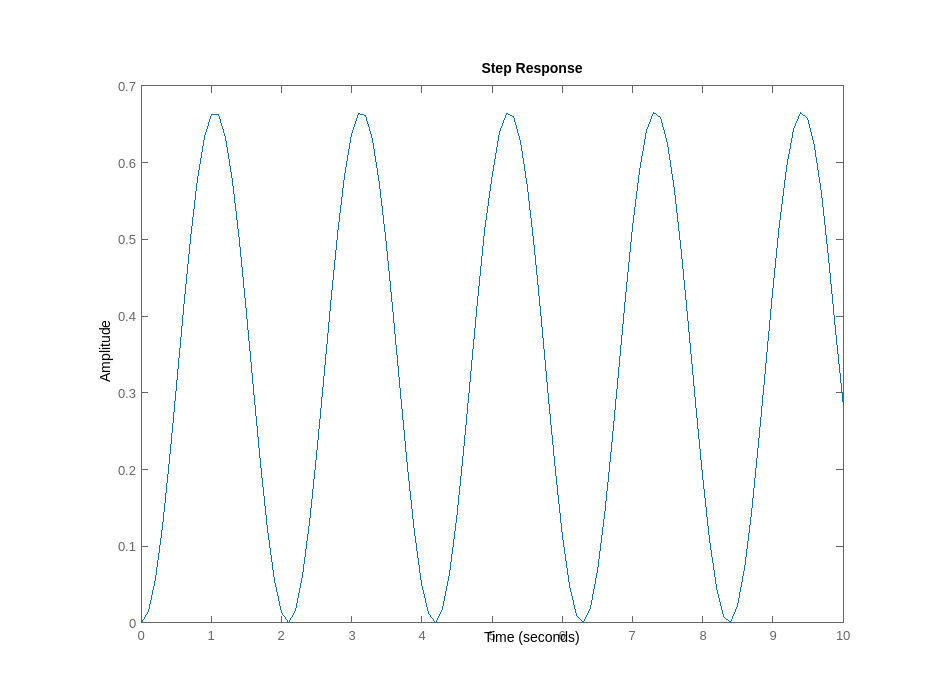

step(G,10)

It has a bounded output for a step input so why is it not BIBO stable?

What bounded input will cause it to become unbounded?

Use the bounded input that has the same poles as the plant $G(s)$.

So we will use $\sin 3t$ as the input.

clear
syms s t G R C c
G(s)=3/(s^2+9)

$$G(s) = \frac{3}{s^{2}+9}$$

R(s)=laplace(sin(3*t))

$$R(s) = \frac{3}{s^{2}+9}$$

C(s)=G(s)*R(s)

$$C(s) = \frac{9}{{\left(s^{2}+9\right)}^{2}}$$

partfrac(C(s))

$$ans = \frac{9}{{\left(s^{2}+9\right)}^{2}}$$

c(t)=ilaplace(C(s))

$$c(t) = \frac{\sin\left(3\,t\right)}{6}-\frac{t\,\cos\left(3\,t\right)}{2}$$

laplace(c(t))

$$ans = \frac{1}{s^{2}+9}-\frac{s^{2}}{{\left(s^{2}+9\right)}^{2}}$$

collect(laplace(c(t)))

$$ans = \frac{9}{s^{4}+18\,s^{2}+81}$$

If we want to understand how ${\cal L}^{-1}\left\{\frac{9}{(s^2+9)^2}\right\}=\frac{\sin \left(3\,t\right)}{6}-\frac{t\,\cos \left(3\,t\right)}{2}$, let's consider where its poles are and what a complex valued partial fractions expansion looks like.

    [n,d]=numden(C)

$$n(s) = 9$$

$$d(s) = {\left(s^{2}+9\right)}^{2}$$

solve(d==0)

$$ans = \left(\begin{array}{c} -3\,\mathrm{i}\\ -3\,\mathrm{i}\\ 3\,\mathrm{i}\\ 3\,\mathrm{i} \end{array}\right)$$

So we have 


$$\begin{array}{rcl}\frac{9}{(s^2+9)^2}&=&\frac{9}{(s+j3)^2 (s-j3)^2\end{array}$$


which has partial fractions expansion:

syms A B C D
9/(s^2+9)^2==A/(s+j*3)+B/(s+j*3)^2+C/(s-j*3)+D/(s-j*3)^2

$$ans = \frac{9}{{\left(s^{2}+9\right)}^{2}}=\frac{A}{s+3\,\mathrm{i}}+\frac{B}{{\left(s+3\,\mathrm{i}\right)}^{2}}+\frac{C}{s-3\,\mathrm{i}}+\frac{\text{D}}{{\left(s-3\,\mathrm{i}\right)}^{2}}$$

collect(ans)

$$ans = \begin{array}{l} \frac{9}{\sigma_{1}}=\frac{\left(A+C\right)\,s^{3}+\left(B+\text{D}-3\,A\,\mathrm{i}+3\,C\,\mathrm{i}\right)\,s^{2}+\left(9\,A-6\,B\,\mathrm{i}+9\,C+6\,\text{D}\,\mathrm{i}\right)\,s-9\,B-9\,\text{D}-27\,A\,\mathrm{i}+27\,C\,\mathrm{i}}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=s^{4}+18\,s^{2}+81 \end{array}$$

equating the numerators we have:

collect(d*ans)

$$ans(s) = 9=\left(A+C\right)\,s^{3}+\left(B+\text{D}-3\,A\,\mathrm{i}+3\,C\,\mathrm{i}\right)\,s^{2}+\left(9\,A-6\,B\,\mathrm{i}+9\,C+6\,\text{D}\,\mathrm{i}\right)\,s-9\,B-9\,\text{D}-27\,A\,\mathrm{i}+27\,C\,\mathrm{i}$$

solving for the coefficients we have

[9,0,0,0]==coeffs(rhs(ans),s)

$$ans(s) = \left(\begin{array}{cccc} 9=-9\,B-9\,\text{D}-27\,A\,\mathrm{i}+27\,C\,\mathrm{i} & 0=9\,A-6\,B\,\mathrm{i}+9\,C+6\,\text{D}\,\mathrm{i} & 0=B+\text{D}-3\,A\,\mathrm{i}+3\,C\,\mathrm{i} & 0=A+C \end{array}\right)$$

solve(ans,[A,B,C,D])

ans = struct with fields:
    A: 1i/12
    B: -1/4
    C: -1i/12
    D: -1/4


subs(A/(s+j*3)+B/(s+j*3)^2+C/(s-j*3)+D/(s-j*3)^2,[A,B,C,D],[ans.A,ans.B,ans.C,ans.D])

$$ans = -\frac{\mathrm{i}}{12\,\left(s-3\,\mathrm{i}\right)}+\frac{\mathrm{i}}{12\,\left(s+3\,\mathrm{i}\right)}-\frac{1}{4\,{\left(s-3\,\mathrm{i}\right)}^{2}}-\frac{1}{4\,{\left(s+3\,\mathrm{i}\right)}^{2}}$$

ilaplace(ans)

$$ans = \frac{{\mathrm{e}}^{-3\,t\,\mathrm{i}}\,\mathrm{i}}{12}-\frac{{\mathrm{e}}^{3\,t\,\mathrm{i}}\,\mathrm{i}}{12}-\frac{t\,{\mathrm{e}}^{-3\,t\,\mathrm{i}}}{4}-\frac{t\,{\mathrm{e}}^{3\,t\,\mathrm{i}}}{4}$$

simplify(c==ans)

$$ans(t) = \mathrm{symtrue}$$

c

$$c(t) = \frac{\sin\left(3\,t\right)}{6}-\frac{t\,\cos\left(3\,t\right)}{2}$$

Switching from symbolic to numeric models in matlab:

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



G=3/(s^2+9)

G =
 
     3
  -------
  s^2 + 9
 
Continuous-time transfer function.



R=3/(s^2+9)

R =
 
     3
  -------
  s^2 + 9
 
Continuous-time transfer function.



C=G*R

C =
 
          9
  -----------------
  s^4 + 18 s^2 + 81
 
Continuous-time transfer function.



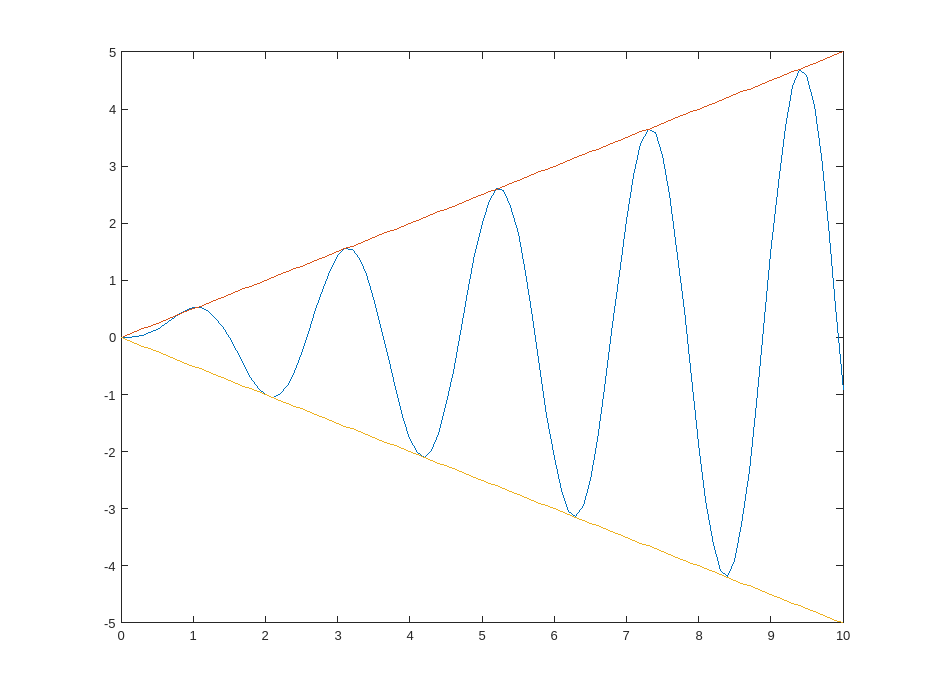

[y,t]=impulse(C,10);
plot(t,y,t,1/2*t,t,-1/2*t)

What happens if we input a bounded sinusiod that does not correspond to the exact frequency of the poles on the $j\omega$ axis but instead is very close to the frequency?

R2=3.01/(s^2+3.01^2)

R2 =
 
     3.01
  ----------
  s^2 + 9.06
 
Continuous-time transfer function.



C2=G*R2

C2 =
 
           9.03
  -----------------------
  s^4 + 18.06 s^2 + 81.54
 
Continuous-time transfer function.



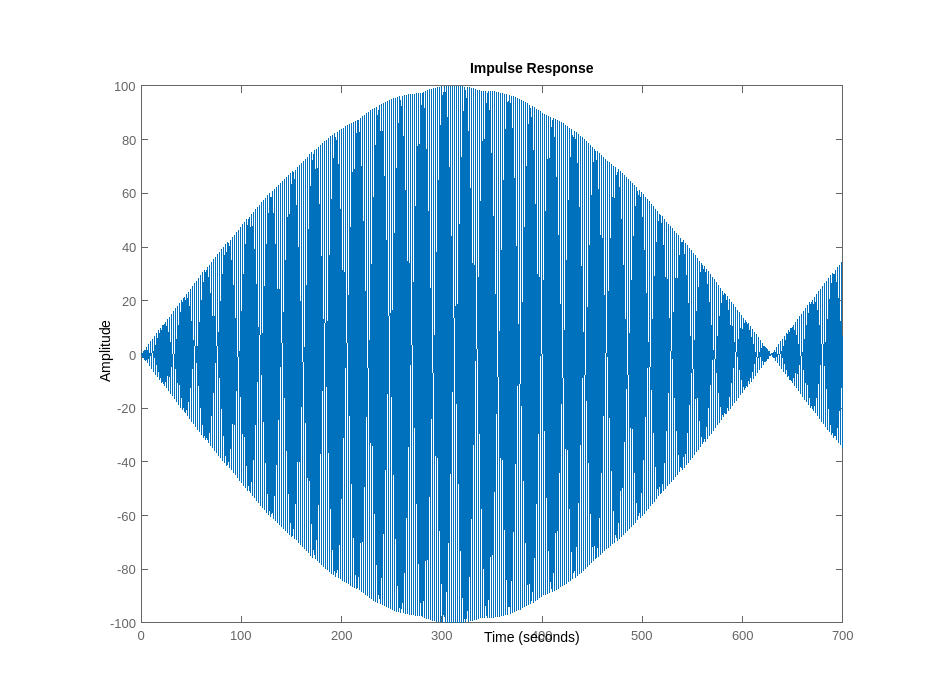

impulse(C2,700)

We get oscillations at the frequencey of the forcing function that have lage oscillations in amplitude but are bounded!

Suppose we have a system that is only just BIBO stable, say with poles at $-0.01 \pm j 3$. What happens when you excite it at its resonant frequency of 3 rad/s? 

syms s t
abs(0.01+j*3)^2/((s+0.01-j*3)*(s+0.01+j*3))

$$ans = \frac{90001}{10000\,\left(s+\frac{1}{100}-3\,\mathrm{i}\right)\,\left(s+\frac{1}{100}+3\,\mathrm{i}\right)}$$

Gstable=collect(ans)

$$Gstable = \frac{90001}{10000\,s^{2}+200\,s+90001}$$

R=laplace(sin(3*t))

$$R = \frac{3}{s^{2}+9}$$

ilaplace(Gstable*R)

$$ans = \frac{90001\,\sin\left(3\,t\right)}{360001}-\frac{54000600\,\cos\left(3\,t\right)}{360001}+\frac{54000600\,{\mathrm{e}}^{-\frac{t}{100}}\,\left(\cos\left(3\,t\right)+\frac{\sin\left(3\,t\right)}{600}\right)}{360001}$$

So in the steady state we'll get very large oscillations - a unit sin input results in orders of magnitude large sinusoidal output!

Let's simulate this to see what it looks like

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



Gbibo=9.0001/(s^2+.02*s+9.0001)

Gbibo =
 
         9
  ----------------
  s^2 + 0.02 s + 9
 
Continuous-time transfer function.



R=3/(s^2+9)

R =
 
     3
  -------
  s^2 + 9
 
Continuous-time transfer function.



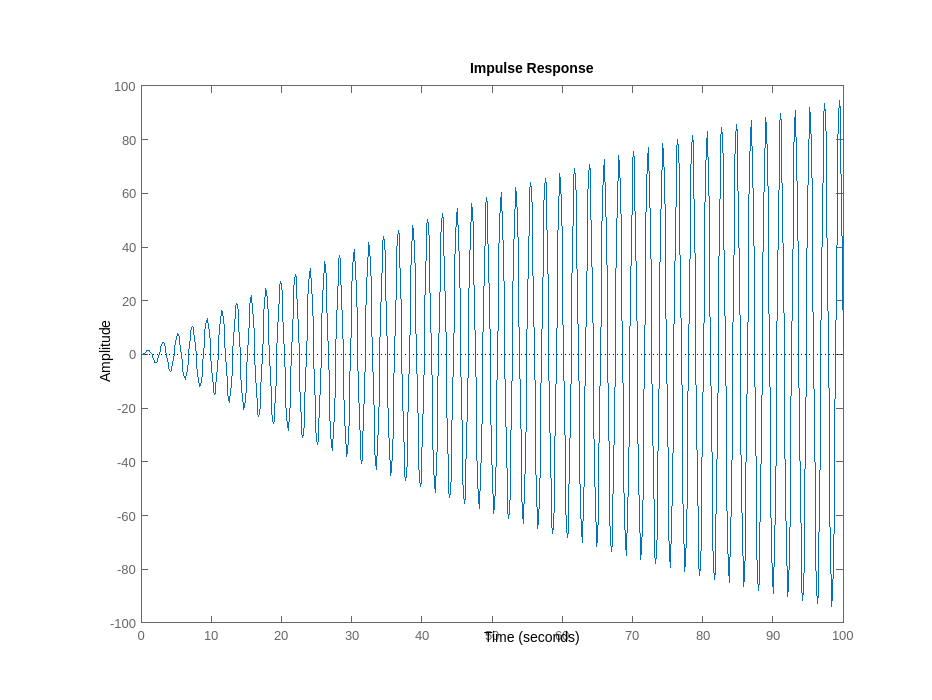

impulse(Gbibo*R,100)

Oscillations quickly grow to $t=100$. 

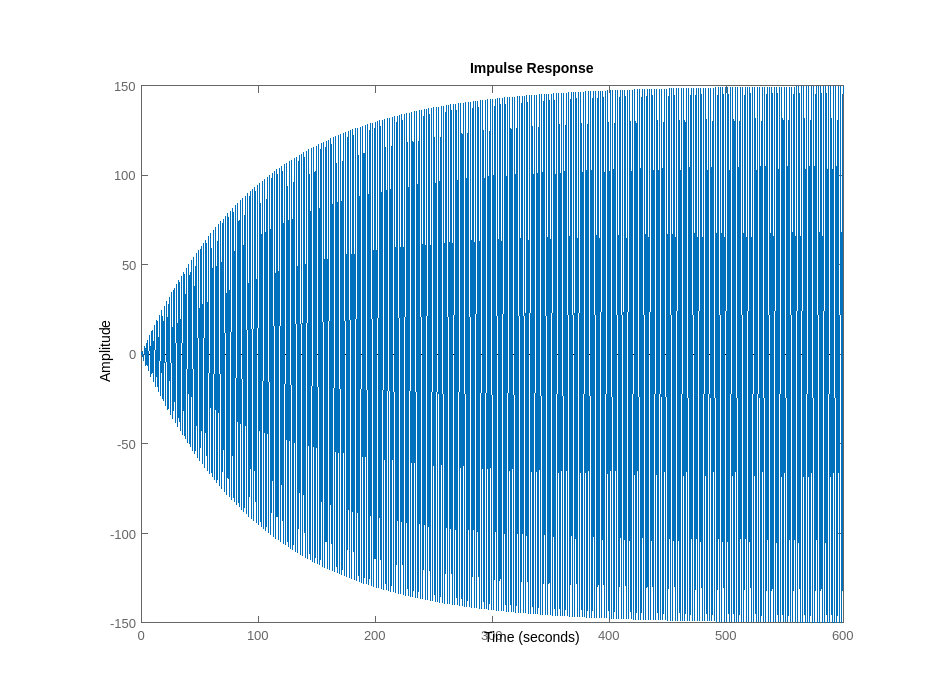

impulse(Gbibo*R)

And in steady state have an amplitude of about 150. So the system is BIBO stable, but has a resonance frequency corresponding to the imaginary parts of the poles that are close the the $j\omega$ axis that could cause problems.

### Checking stabilty numerically in Matlab

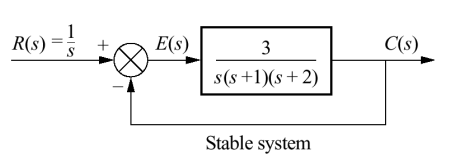

clear
G=zpk([],[0 -1 -2],1)

G =
 
        1
  -------------
  s (s+1) (s+2)
 
Continuous-time zero/pole/gain model.



K=3

K = 3

we can compute the closed loop transfer function:

# 
$$G_\textit{cl}(s)=\frac{G(s)}{1+G(s)H(s)}$$


where $K=3$, $G(s)=\frac{1}{s(s+1)(s+2)}$, and $H(s)=1$. This is done in matlab with the $\texttt{feedback(G,H)}$" command (type "help feedback" at the matlab command prompt for details)

G_cl=feedback(K*G,1)

G_cl =
 
                  3
  ---------------------------------
  (s+2.672) (s^2 + 0.3283s + 1.123)
 
Continuous-time zero/pole/gain model.



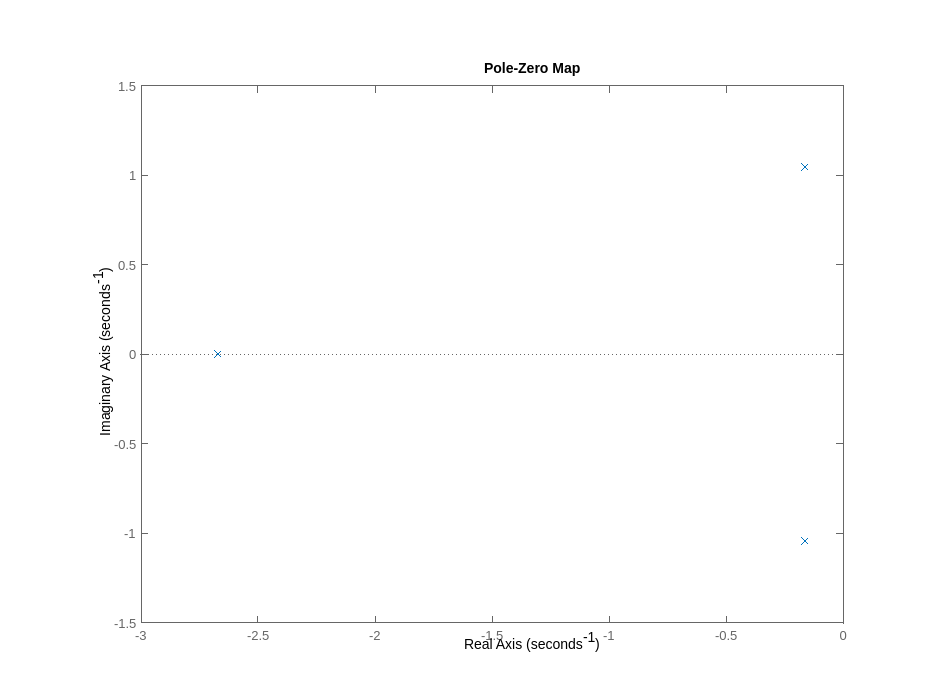

pzmap(G_cl)

pole(G_cl)

ans =   -2.6717 + 0.0000i
  -0.1642 + 1.0469i
  -0.1642 - 1.0469i


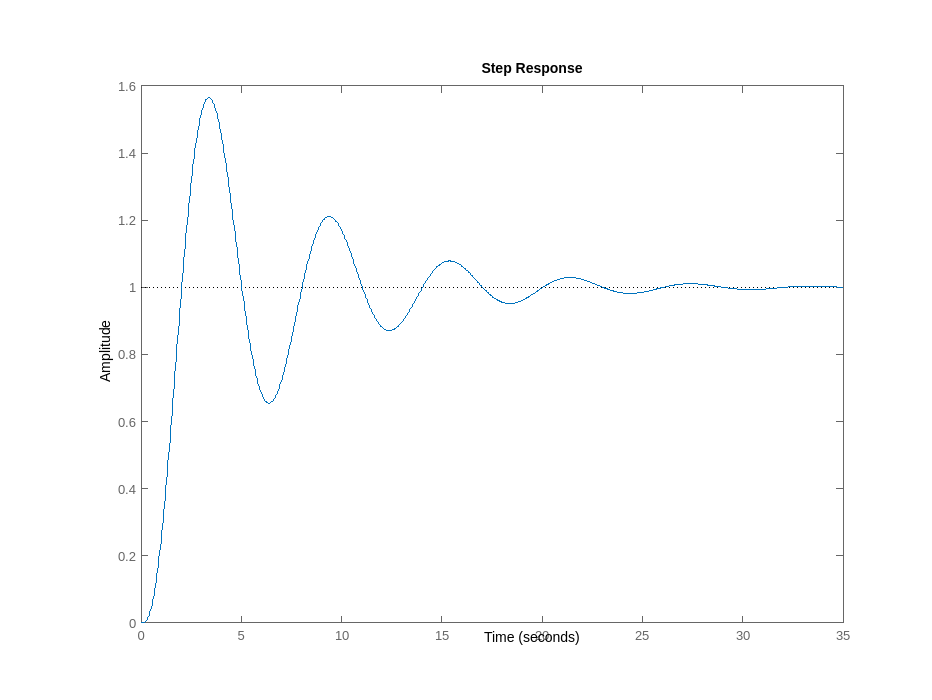

step(G_cl)

Now lets consider the system with a gain of 7.

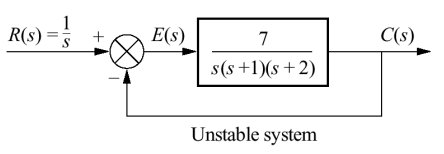

K=7

K = 7

G_cl=feedback(K*G,1)

G_cl =
 
                  7
  ----------------------------------
  (s+3.087) (s^2 - 0.08675s + 2.268)
 
Continuous-time zero/pole/gain model.



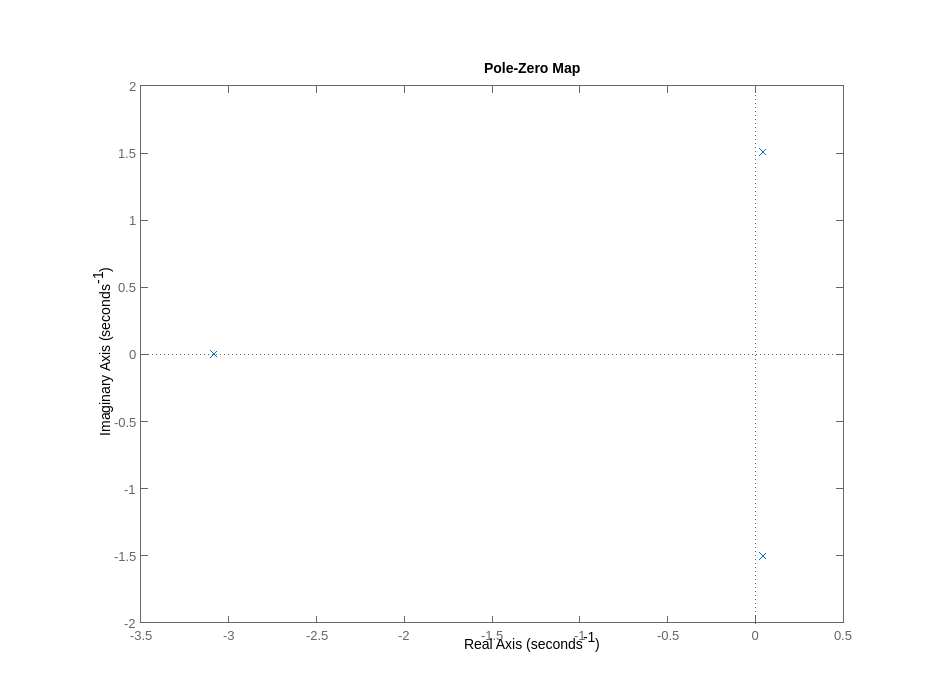

pzmap(G_cl)

pole(G_cl)

ans =    0.0434 + 1.5053i
   0.0434 - 1.5053i
  -3.0867 + 0.0000i


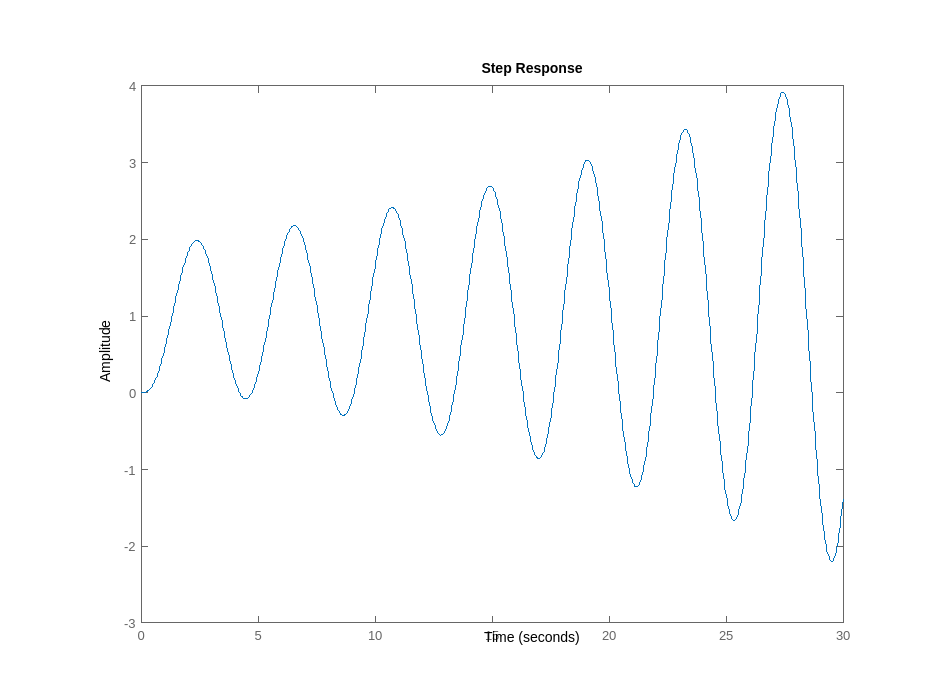

step(G_cl,30)

Consider the system:

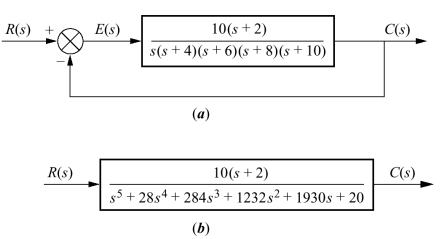

G=zpk([-2],[0 -4 -6 -8 -10],10)

G =
 
           10 (s+2)
  --------------------------
  s (s+4) (s+6) (s+8) (s+10)
 
Continuous-time zero/pole/gain model.



Compute the closed loop transfer function from the bottom part of the figure (b)

G_cl=feedback(G,1)

G_cl =
 
                             
                     10 (s+2)
                             
  ----------------------------------------------
                                                
  (s+0.01043) (s+4.12) (s+5.619) (s+8.452)      
                                                
                                       (s+9.799)
                                                
 
Continuous-time zero/pole/gain model.



Check stability by finding the location of the poles of the closed loop transfer function.

pole(G_cl)

ans =    -0.0104
   -9.7992
   -8.4517
   -5.6186
   -4.1200


Alternatively we could have entered the transfere function as:

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



G=10*(s+2)/(s*(s+4)*(s+6)*(s+8)*(s+10))

G =
 
                  10 s + 20
  ------------------------------------------
  s^5 + 28 s^4 + 284 s^3 + 1232 s^2 + 1920 s
 
Continuous-time transfer function.



G_cl=feedback(G,1)

G_cl =
 
                             
                    10 s + 20
                             
  ----------------------------------------------
                                                
  s^5 + 28 s^4 + 284 s^3 + 1232 s^2 + 1930 s    
                                                
                                            + 20
                                                
 
Continuous-time transfer function.



pole(G_cl)

ans =    -9.7992
   -8.4517
   -5.6186
   -4.1200
   -0.0104


### Routh-Hurwitz Criterion

What if you don't have matlab? Or would like to determine the range of gains $K$ that the closed loop system is stable?

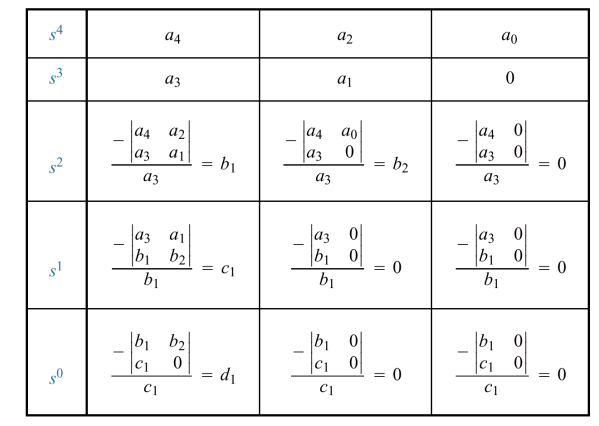

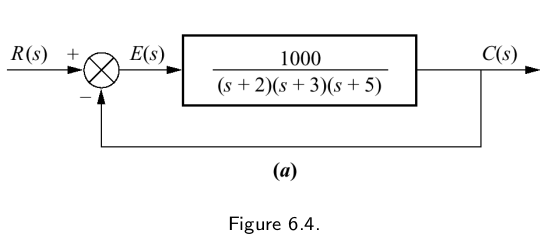

syms s G G_cl
G(s)=1000/((s+2)*(s+3)*(s+5))

$$G(s) = \frac{1000}{\left(s+2\right)\,\left(s+3\right)\,\left(s+5\right)}$$

G_cl(s)=collect(G(s)/(1+G(s)))

$$G\_cl(s) = \frac{1000}{s^{3}+10\,s^{2}+31\,s+1030}$$

[num,den]=numden(G_cl)

$$num(s) = 1000$$

$$den(s) = s^{3}+10\,s^{2}+31\,s+1030$$

coeffs(den)

$$ans(s) = \left(\begin{array}{cccc} 1030 & 31 & 10 & 1 \end{array}\right)$$

double(coeffs(den))

ans =         1030          31          10           1


den=flip(double(coeffs(den)))

den =            1          10          31        1030


n=length(den)-1

n = 3

RT=[s^n den(1:2:end);s^(n-1) den(2:2:end)]

$$RT = \left(\begin{array}{ccc} s^{3} & 1 & 31\\ s^{2} & 10 & 1030 \end{array}\right)$$

%RT=[s^3 1 31;s^2 1 103]
RT=[RT;s^1 -det([RT(1,2) RT(1,3);RT(2,2) RT(2,3)])/RT(2,2) -det([RT(1,2) 0;RT(2,2) 0])/RT(2,2) ]

$$RT = \left(\begin{array}{ccc} s^{3} & 1 & 31\\ s^{2} & 10 & 1030\\ s & -72 & 0 \end{array}\right)$$

RT=[RT;s^0 -det([RT(2,2) RT(2,3);RT(3,2) RT(3,3)])/RT(3,2) -det([RT(2,2) 0;RT(3,2) 0])/RT(3,2) ]

$$RT = \left(\begin{array}{ccc} s^{3} & 1 & 31\\ s^{2} & 10 & 1030\\ s & -72 & 0\\ 1 & 1030 & 0 \end{array}\right)$$

Two sign changes in the first row so there should be 2 poles in the right have plane.

Check numierically:

roots([1 10 31 1030])

ans =  -13.4136 + 0.0000i
   1.7068 + 8.5950i
   1.7068 - 8.5950i


Or   

G=zpk([],[-2 -3 -5],1000)

G =
 
        1000
  -----------------
  (s+2) (s+3) (s+5)
 
Continuous-time zero/pole/gain model.



Gcl=feedback(G,1)

Gcl =
 
                1000
  --------------------------------
  (s+13.41) (s^2 - 3.414s + 76.79)
 
Continuous-time zero/pole/gain model.



pole(Gcl)

ans =  -13.4136 + 0.0000i
   1.7068 + 8.5950i
   1.7068 - 8.5950i


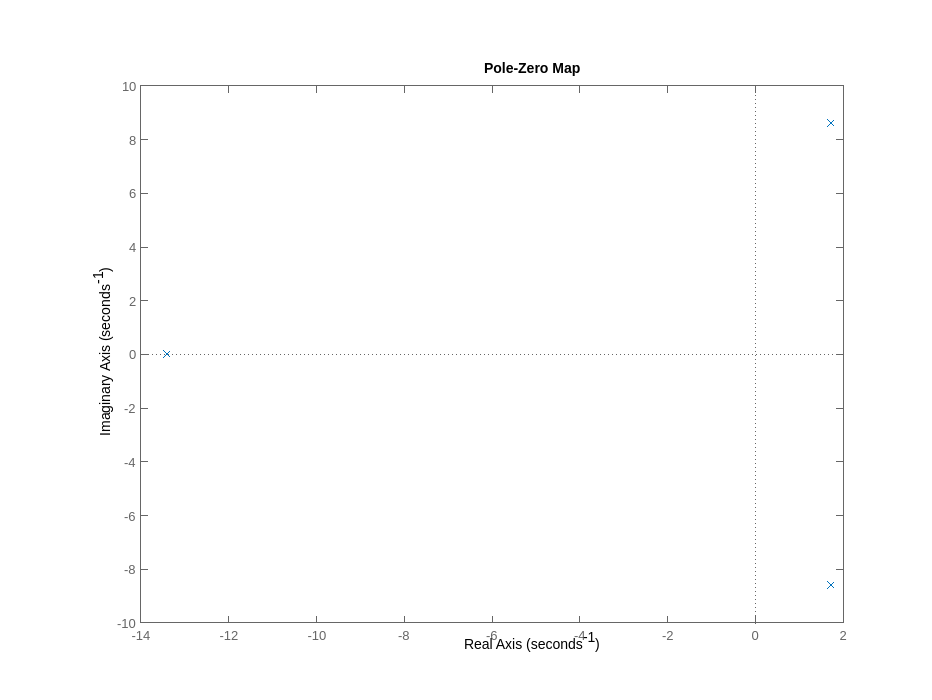

pzmap(Gcl)

We see that we indeed have 2 poles in the RHP for the closed loop system in Fig. 6.4.

syms s
RT=[s^5 1 284 1930;s^4 28 1232 20]

$$RT = \left(\begin{array}{cccc} s^{5} & 1 & 284 & 1930\\ s^{4} & 28 & 1232 & 20 \end{array}\right)$$

RT=[RT;s^3 -det([RT(1,2) RT(1,3);RT(2,2) RT(2,3)])/RT(2,2) -det([RT(1,2) RT(1,4);RT(2,2) RT(2,4)])/RT(2,2) 0]

$$RT = \left(\begin{array}{cccc} s^{5} & 1 & 284 & 1930\\ s^{4} & 28 & 1232 & 20\\ s^{3} & 240 & \frac{13505}{7} & 0 \end{array}\right)$$

RT=[RT;s^2 -det([RT(2,2) RT(2,3);RT(3,2) RT(3,3)])/RT(3,2) -det([RT(2,2) RT(2,4);RT(3,2) RT(3,4)])/RT(3,2) 0]

$$RT = \left(\begin{array}{cccc} s^{5} & 1 & 284 & 1930\\ s^{4} & 28 & 1232 & 20\\ s^{3} & 240 & \frac{13505}{7} & 0\\ s^{2} & \frac{12083}{12} & 20 & 0 \end{array}\right)$$

RT=[RT;s^1 -det([RT(3,2) RT(3,3);RT(4,2) RT(4,3)])/RT(4,2) -det([RT(3,2) RT(3,4);RT(4,2) RT(4,4)])/RT(4,2) 0]

$$RT = \left(\begin{array}{cccc} s^{5} & 1 & 284 & 1930\\ s^{4} & 28 & 1232 & 20\\ s^{3} & 240 & \frac{13505}{7} & 0\\ s^{2} & \frac{12083}{12} & 20 & 0\\ s & \frac{162777715}{84581} & 0 & 0 \end{array}\right)$$

RT=[RT;s^0 -det([RT(4,2) RT(4,3);RT(5,2) RT(5,3)])/RT(5,2) -det([RT(4,2) RT(4,4);RT(5,2) RT(5,4)])/RT(5,2) 0]

$$RT = \left(\begin{array}{cccc} s^{5} & 1 & 284 & 1930\\ s^{4} & 28 & 1232 & 20\\ s^{3} & 240 & \frac{13505}{7} & 0\\ s^{2} & \frac{12083}{12} & 20 & 0\\ s & \frac{162777715}{84581} & 0 & 0\\ 1 & 20 & 0 & 0 \end{array}\right)$$

Consider system:

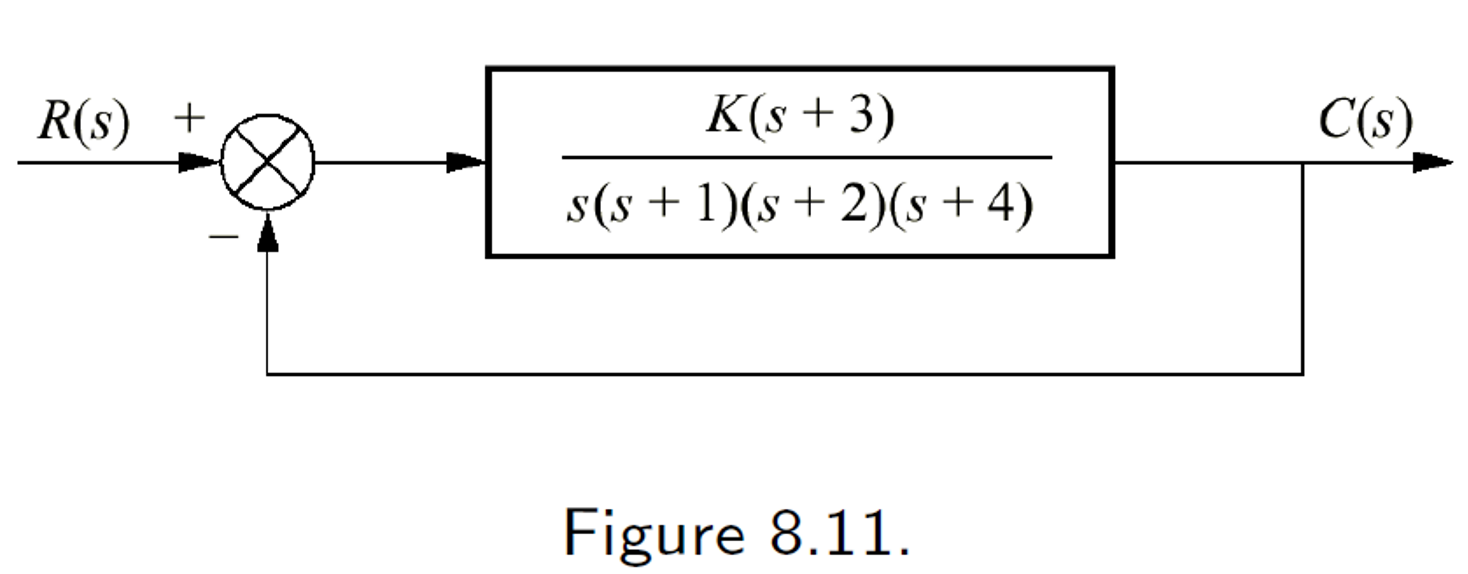

syms K s
G=(s+3)/(s*(s+1)*(s+2)*(s+4))

$$G = \frac{s+3}{s\,\left(s+1\right)\,\left(s+2\right)\,\left(s+4\right)}$$

G_cl=K*G/(1+K*G)

$$G\_cl = \frac{K\,\left(s+3\right)}{s\,\left(\frac{K\,\left(s+3\right)}{s\,\left(s+1\right)\,\left(s+2\right)\,\left(s+4\right)}+1\right)\,\left(s+1\right)\,\left(s+2\right)\,\left(s+4\right)}$$

G_cl=collect(G_cl)

$$G\_cl = \frac{K\,s+3\,K}{s^{4}+7\,s^{3}+14\,s^{2}+\left(K+8\right)\,s+3\,K}$$

clear RT
RT=[s^4 1 14 3*K;s^3 7 K+8 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 14 & 3\,K\\ s^{3} & 7 & K+8 & 0 \end{array}\right)$$

RT=[RT;s^2 -det([RT(1,2) RT(1,3);RT(2,2) RT(2,3)])/RT(2,2) -det([RT(1,2) RT(1,4);RT(2,2) RT(2,4)])/RT(2,2) 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 14 & 3\,K\\ s^{3} & 7 & K+8 & 0\\ s^{2} & \frac{90}{7}-\frac{K}{7} & 3\,K & 0 \end{array}\right)$$

RT=[RT;s^1 -det([RT(2,2) RT(2,3);RT(3,2) RT(3,3)])/RT(3,2) -det([RT(2,2) RT(2,4);RT(3,2) RT(3,4)])/RT(3,2) 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 14 & 3\,K\\ s^{3} & 7 & K+8 & 0\\ s^{2} & \frac{90}{7}-\frac{K}{7} & 3\,K & 0\\ s & \frac{\frac{K^{2}}{7}+\frac{65\,K}{7}-\frac{720}{7}}{\frac{K}{7}-\frac{90}{7}} & 0 & 0 \end{array}\right)$$

RT=[RT;s^0 3*K 0 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 14 & 3\,K\\ s^{3} & 7 & K+8 & 0\\ s^{2} & \frac{90}{7}-\frac{K}{7} & 3\,K & 0\\ s & \frac{\frac{K^{2}}{7}+\frac{65\,K}{7}-\frac{720}{7}}{\frac{K}{7}-\frac{90}{7}} & 0 & 0\\ 1 & 3\,K & 0 & 0 \end{array}\right)$$

assume(K,{'real','positive'})
eqns=[RT(3,2)>0, RT(4,2)>0, RT(5,2)>0]

$$eqns = \left(\begin{array}{ccc} 0<\frac{90}{7}-\frac{K}{7} & 0<\frac{\frac{K^{2}}{7}+\frac{65\,K}{7}-\frac{720}{7}}{\frac{K}{7}-\frac{90}{7}} & 0<3\,K \end{array}\right)$$

solve([K^2+65*K-720==0],K)

$$ans = \frac{7\,\sqrt{145}}{2}-\frac{65}{2}$$

eval(ans)

ans = 9.6456

solve([90-K>0,K^2/7+65/7*K-720/7>0],K)

$$ans = \frac{\sqrt{7105}}{4}+\frac{115}{4}$$

eval(ans)

ans = 49.8228

sym f

$$ans = f$$

f(K)=K^2+65*K-720

$$f(K) = K^{2}+65\,K-720$$

Kstar=solve(f(K)==0)

$$Kstar = \frac{7\,\sqrt{145}}{2}-\frac{65}{2}$$

double(Kstar)

ans = 9.6456

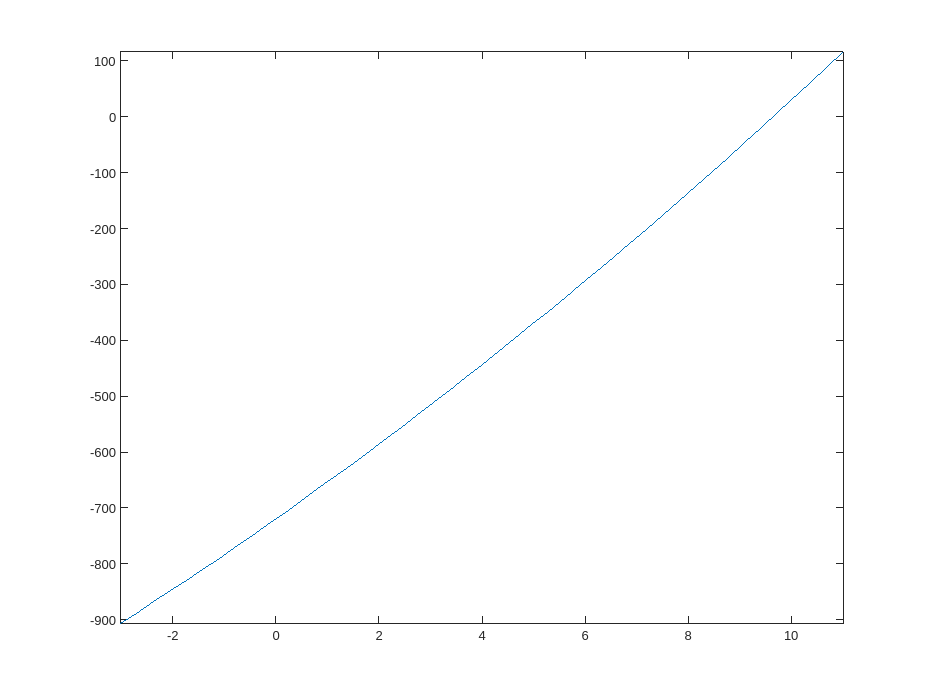

fplot(f,[-3 11])

## Final 2018 

**1. Stability** (25 marks)

a) (5 marks) Is the open loop plant


$$G(s)=\frac{s+3}{s^4 + 23 s^3 + 182 s^2 + 580 s + 600}$$


stable or unstable.

syms s
RT=[s^4 1 182 600;s^3 23 580 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 600\\ s^{3} & 23 & 580 & 0 \end{array}\right)$$

RT=[RT;s^2 -det([RT(1,2) RT(1,3);RT(2,2) RT(2,3)])/RT(2,2) -det([RT(1,2) RT(1,4);RT(2,2) RT(2,4)])/RT(2,2) 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 600\\ s^{3} & 23 & 580 & 0\\ s^{2} & \frac{3606}{23} & 600 & 0 \end{array}\right)$$

RT=[RT;s^1 -det([RT(2,2) RT(2,3);RT(3,2) RT(3,3)])/RT(3,2) -det([RT(2,2) RT(2,4);RT(3,2) RT(3,4)])/RT(3,2) 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 600\\ s^{3} & 23 & 580 & 0\\ s^{2} & \frac{3606}{23} & 600 & 0\\ s & \frac{295680}{601} & 0 & 0 \end{array}\right)$$

RT=[RT;s^0 -det([RT(3,2) RT(3,3);RT(4,2) RT(4,3)])/RT(4,2) -det([RT(3,2) RT(3,4);RT(4,2) RT(4,4)])/RT(4,2) 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 600\\ s^{3} & 23 & 580 & 0\\ s^{2} & \frac{3606}{23} & 600 & 0\\ s & \frac{295680}{601} & 0 & 0\\ 1 & 600 & 0 & 0 \end{array}\right)$$

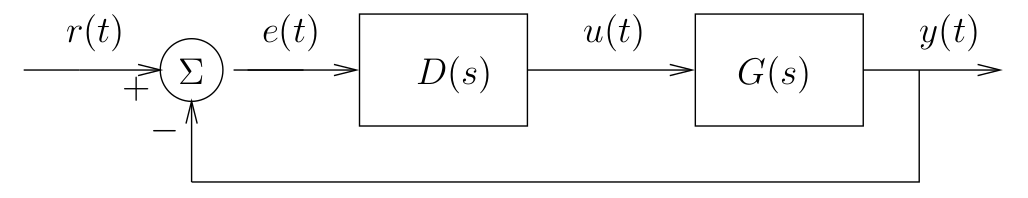

Consider the system shown above where:


$$D(s)=K\;\mbox{ and } \;G(s)=\frac{s+3}{s^4 + 23 s^3 + 182 s^2 + 580 s + 600}=\frac{s+3}{(s+2)(s+5)(s+6)(s+10)}$$


b) (5 marks) Compute the closed loop transfer function of the system

syms sigma s K 
G=zpk([-3],[-2 -5 -6 -10],1)

G =
 
           (s+3)
  ------------------------
  (s+2) (s+5) (s+6) (s+10)
 
Continuous-time zero/pole/gain model.



[num,den]=tfdata(G)

num = 1×1 cell array
    {[0 0 0 1 3]}


den = 1×1 cell array
    {[1 23 182 580 600]}


Gs=poly2sym(cell2mat(num),s)/poly2sym(cell2mat(den),s)

$$Gs = \frac{s+3}{s^{4}+23\,s^{3}+182\,s^{2}+580\,s+600}$$

Gcls=K*Gs/(1+K*Gs)

$$Gcls = \frac{K\,\left(s+3\right)}{\left(\frac{K\,\left(s+3\right)}{s^{4}+23\,s^{3}+182\,s^{2}+580\,s+600}+1\right)\,\left(s^{4}+23\,s^{3}+182\,s^{2}+580\,s+600\right)}$$

c) (10 marks) For what values of K is the closed loop system stable?

Gcls=collect(simplifyFraction(Gcls))

$$Gcls = \frac{K\,s+3\,K}{s^{4}+23\,s^{3}+182\,s^{2}+\left(K+580\right)\,s+3\,K+600}$$

RT=[s^4 1 182 3*K+600;s^3 23 K+580 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 3\,K+600\\ s^{3} & 23 & K+580 & 0 \end{array}\right)$$

RT=[RT;s^2 -det([RT(1,2) RT(1,3);RT(2,2) RT(2,3)])/RT(2,2) -det([RT(1,2) RT(1,4);RT(2,2) RT(2,4)])/RT(2,2) 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 3\,K+600\\ s^{3} & 23 & K+580 & 0\\ s^{2} & \frac{3606}{23}-\frac{K}{23} & 3\,K+600 & 0 \end{array}\right)$$

Multypliy $s^2$ row by 23.

RT(3,2)=23*RT(3,2)

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 3\,K+600\\ s^{3} & 23 & K+580 & 0\\ s^{2} & 3606-K & 3\,K+600 & 0 \end{array}\right)$$

RT(3,3)=23*RT(3,3)

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 3\,K+600\\ s^{3} & 23 & K+580 & 0\\ s^{2} & 3606-K & 69\,K+13800 & 0 \end{array}\right)$$

Now continue.

RT=[RT;s^1 -det([RT(2,2) RT(2,3);RT(3,2) RT(3,3)])/RT(3,2) -det([RT(2,2) RT(2,4);RT(3,2) RT(3,4)])/RT(3,2) 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 3\,K+600\\ s^{3} & 23 & K+580 & 0\\ s^{2} & 3606-K & 69\,K+13800 & 0\\ s & -\frac{-K^{2}+1439\,K+1774080}{K-3606} & 0 & 0 \end{array}\right)$$

RT=[RT;s^0 -det([RT(3,2) RT(3,3);RT(4,2) RT(4,3)])/RT(4,2) -det([RT(3,2) RT(3,4);RT(4,2) RT(4,4)])/RT(4,2) 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 3\,K+600\\ s^{3} & 23 & K+580 & 0\\ s^{2} & 3606-K & 69\,K+13800 & 0\\ s & -\frac{-K^{2}+1439\,K+1774080}{K-3606} & 0 & 0\\ 1 & 69\,K+13800 & 0 & 0 \end{array}\right)$$

RT(4,2)=simplifyFraction(RT(4,2))

$$RT = \left(\begin{array}{cccc} s^{4} & 1 & 182 & 3\,K+600\\ s^{3} & 23 & K+580 & 0\\ s^{2} & 3606-K & 69\,K+13800 & 0\\ s & -\frac{-K^{2}+1439\,K+1774080}{K-3606} & 0 & 0\\ 1 & 69\,K+13800 & 0 & 0 \end{array}\right)$$

$s^2$ row gives us $K<3606$ for stability.

Consider the $s$ row. We can force a row of all zeroz when $-K^2+1439K+1774080=0$. This may be where poles cross the $j\omega$ axis.

maybeK=roots([-1 1439 1774080])

maybeK = 1.0e+03 *

    2.2334
   -0.7944


Compute the closed loop system for

K=maybeK(1)

K = 2.2334e+03

feedback(K*G,1)

ans =
 
            2233.4 (s+3)
  ---------------------------------
  (s+20.02) (s+2.981) (s^2 + 122.3)
 
Continuous-time zero/pole/gain model.



pole(ans)

ans =  -20.0188 + 0.0000i
   0.0000 +11.0598i
   0.0000 -11.0598i
  -2.9812 + 0.0000i


### Stability in State Space

We know that for any statespace representation of a system, if we convert it into a Transfer function


$$\underline{\dot{x}}  =  \underline{A}\, \underline{x}  + \underline{B} \, \underline{u}    \mbox{\ }\mbox{\ }  \mbox{state equations}\\
\underline{y}  =  \underline{C}\, \underline{x}  + \underline{D} \, \underline{u}    \mbox{\ }\mbox{\ }  \mbox{output equations}&$$


We cab convert it into a transfer function by:


$$G(s) = \frac{Y(s)}{U(s)} =      \underline{C}(s\underline{I} - \underline{A})^{-1}\underline{B}   + \underline{D}\\
\mbox{    }= \underline{C} \frac{\mbox{adj}([s\underline{I} - \underline{A}])}{\mbox{det}([s\underline{I} - \underline{A}])}\underline{B}   + \underline{D}\\$$


so the characteristic equation of matrix $\underline{A}$, ie. $\mbox{det}([s\underline{I} - \underline{A}])$=0 corresponds to the poles of the transfer function.

But the solution to this equation is just the eigenvalues for $\underline{A}$.

For example, consider:

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



G=10/(s^5+2*s^4+3*s^3+6*s^2+5*s+3)

G =
 
                   10
  -------------------------------------
  s^5 + 2 s^4 + 3 s^3 + 6 s^2 + 5 s + 3
 
Continuous-time transfer function.



which has Controller Canonical Statespace representation:

A=[0 1 0 0 0;0 0 1 0 0;0 0 0 1 0; 0 0 0 0 1; -3 -5 -6 -3 -2]

A =      0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1
    -3    -5    -6    -3    -2


B=[0 0 0 0 1]'

B =      0
     0
     0
     0
     1


C=[10 0 0 0 0]

C =     10     0     0     0     0



pole(G)

ans =    0.3429 + 1.5083i
   0.3429 - 1.5083i
  -1.6681 + 0.0000i
  -0.5088 + 0.7020i
  -0.5088 - 0.7020i


eig(A)

ans =    0.3429 + 1.5083i
   0.3429 - 1.5083i
  -1.6681 + 0.0000i
  -0.5088 + 0.7020i
  -0.5088 - 0.7020i


Note that the poles of G and eigenvalues of $\underline{A}$ are the exact same! So the statespace system is stable iff all of the eigenvalues of $\underline{A}$ are in the open LHP.